
folderPath = 'C:\Users\omgui\Desktop\BASDL\dataset_testing';  % CHANGE THIS to your folder path
fileList = dir(fullfile(folderPath, 'arrivalTimes*.mat'));
fileList = sort({fileList.name});  % alphabetical order

% Constants
w0 = 3e-7;
S_fixed = 3;

% Preallocate axes handles for subplot grid
fcsFig = figure('Name','FCS Analysis of Upper & Lower Bound of Simulation Inputs',...
                'NumberTitle','off','Color','w','Units','normalized',...
                'Position',[0.1 0.1 0.8 0.8]);
sgtitle('FCS Analysis of Upper & Lower Bound of Simulation Inputs','FontSize',16);

% Dictionary to map conc/amp to subplot row/col
subplotGrid = containers.Map();

% Populate subplot grid key for ordering
% Extract all conc and amp pairs from filenames
allKeys = {};
allConcs = {};
allAmps = {};

for i = 1:length(fileList)
    tokens = regexp(fileList{i}, 'arrivalTimes([\dEe\-\+\.]+)_([\dEe\-\+\.]+)\.mat', 'tokens');
    if ~isempty(tokens)
        conc = tokens{1}{1};
        amp = tokens{1}{2};
        allKeys{end+1} = sprintf('%s_%s', conc, amp);
        allConcs{end+1} = conc;
        allAmps{end+1} = amp;
    end
end

% Determine unique row and column labels
rowLabels = unique(allConcs);
colLabels = unique(allAmps);

% Build the subplotGrid map
subplotGrid = containers.Map();
for r = 1:numel(rowLabels)
    for c = 1:numel(colLabels)
        key = sprintf('%s_%s', rowLabels{r}, colLabels{c});
        subplotGrid(key) = sub2ind([length(rowLabels), length(colLabels)], r, c);  % row-major
    end
end

% Shared axes storage
global FCS_subplot_axes;
FCS_subplot_axes = gobjects(9,1);

% Run interactive GUI 9x
for i = 1:length(fileList)
    fileName = fileList{i};
    fprintf('Loading file: %s\n', fileName);

    data = load(fullfile(folderPath, fileName));
    arrivalTimes = data.arrivalTimes;

    % Parse conc and amp from filename
    tokens = regexp(fileName, 'arrivalTimes([\dEe\-\+\.]+)_([\dEe\-\+\.]+)\.mat', 'tokens');
    if isempty(tokens)
        error('Filename "%s" is not in expected format.', fileName);
    end
    conc = tokens{1}{1};
    amp  = tokens{1}{2};
    
    subplotKey = sprintf('%s_%s', conc, amp);
    subplotIdx = subplotGrid(subplotKey);

    % Save current axes handle for subplot position
    FCS_subplot_axes(subplotIdx) = subplot(3,3,subplotIdx,'Parent',fcsFig);

    % Launch GUI and wait for interaction
    Copy_of_InteractiveFCSArrivalPlot_flow(arrivalTimes, w0, S_fixed, FCS_subplot_axes(subplotIdx), conc, amp);
    uiwait;  % Wait for user to press "Add to Grid" in GUI
end

Loading file: arrivalTimes4e-11_1000.mat
Loading file: arrivalTimes4e-11_10500.mat


Loading file: arrivalTimes4e-11_5250.mat


Loading file: arrivalTimes7e-11_1000.mat


Loading file: arrivalTimes7e-11_10500.mat


Loading file: arrivalTimes7e-11_5250.mat


Loading file: arrivalTimes9e-12_1000.mat


Loading file: arrivalTimes9e-12_10500.mat


Loading file: arrivalTimes9e-12_5250.mat


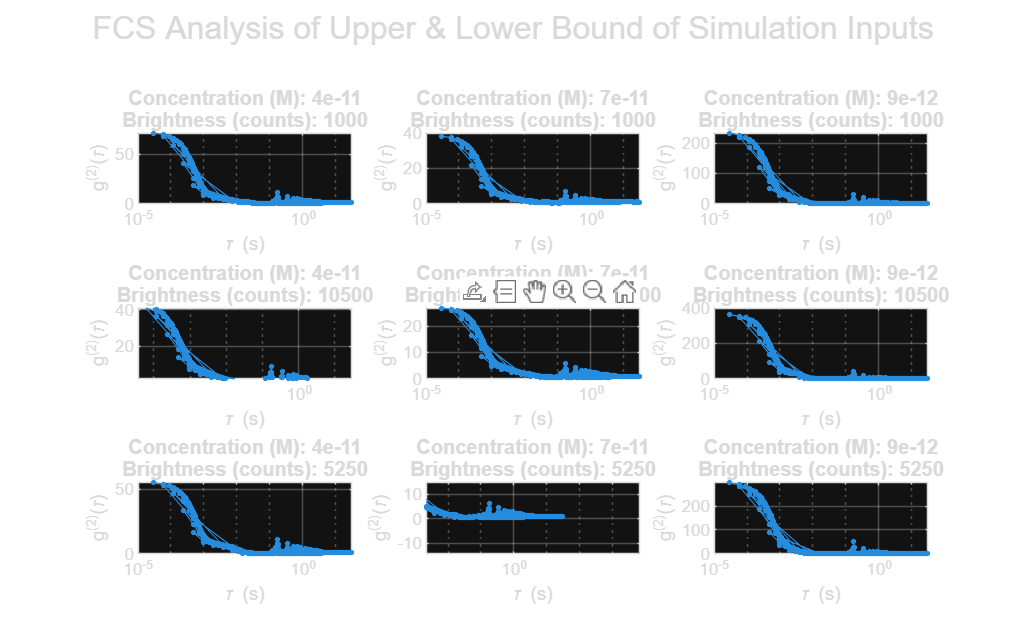


% Save final figure
saveas(fcsFig, fullfile(folderPath, 'FCS_Grid.png'));

disp('Saved full grid plot.');

Saved full grid plot.
